# Windkessel model

Copyright (C) [2020](#2020)  [Bolic](#Miodrag)

  This program is free software: you can redistribute it and/or modify   it under the terms of the GNU General Public License as published by  the Free Software Foundation, either version 3 of the License, or  (at your option) any later version.  This program is distributed in the hope that it will be useful, but WITHOUT ANY WARRANTY; without even the implied warranty of MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE.  See the GNU General Public License for more details <https://www.gnu.org/licenses/>. 

This code was developed by Miodrag Bolic for the book PERVASIVE CARDIAC AND RESPIRATORY MONITORING DEVICES.

## Introduction

### The Windkessel model 

The Windkessel model is an interpretative model that allows us to achieve the following:

Given the aortic flow and the parameters of the model, we can generate aortic and peripheral pressure signals. 

Given the aortic flow and the aortic pressure, we can estimate the values of parameters such as arterial compliance that have physiological meaning and can be interpreted. 

The pressure  plays the role of the voltage at different points and the blood flow  of the current.

Parameters include:

- Z0 is the characteristic impedance of the artery

- R is the peripheral resistance 

- CA is the arterial compliance which is the change in arterial blood volume (due to a given change in arterial blood pressure, 

- L is the arterial inertance and it is defined as the change in pressure in the arterial segment versus the acceleration of the blood.

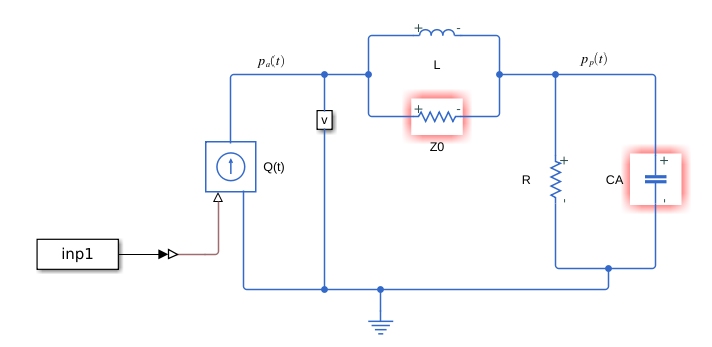

In this section Windkessel model will be presented. 

### Forward modeling

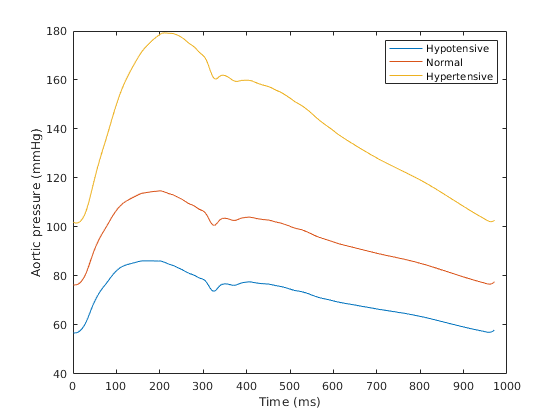

% Modeling Case 1

load('data_17s.mat')
a=[];
fs=200;
src1=zeros(200,0);
global start_pulse_ind;
global end_pulse_ind;
start_pulse_ind=15800;
end_pulse_ind=16841;
%src1=240*ones(65,1);
inp1(:,2)=TFP(:,2);  % flow
inp1(:,1)=TFP(:,1);
model_name = 'WK';
open_system(model_name)
param=[0.039 1.95 0.71 0.011; 0.043 1.5 0.95 0.015; 0.05 0.7 1.4 0.02];
%param=[3 2 0.6 0.005];
cases=['hypotensive', 'normotensive', 'hypertensive'];
figure
for level =1:3
   
    
    L = sdo.getParameterFromModel(model_name, 'L');
    L.Value=param(level,4);
    sdo.setValueInModel(model_name,L);
    
    Z0 = sdo.getParameterFromModel(model_name, 'Z0');
    Z0.Value=param(level,1);
    sdo.setValueInModel(model_name,Z0);
    
    R = sdo.getParameterFromModel(model_name, 'R');
    R.Value=param(level,3);
    sdo.setValueInModel(model_name,R);
    
    CA = sdo.getParameterFromModel(model_name, 'CA');
    CA.Value=param(level,2);
    sdo.setValueInModel(model_name,CA);
    
    % Collect these parameters into a vector.
    v = [L Z0 R CA];
    
    simOut = sim(model_name, 'CaptureErrors', 'on');
    %figure
    %plot(simOut.simout.Time, simOut.simout.Data)
    plot(simOut.simout.Data(14000:14970))
    hold on
end
xlabel("Time (ms)")
ylabel("Aortic pressure (mmHg)")
legend({'Hypotensive', 'Normal', 'Hypertensive'})

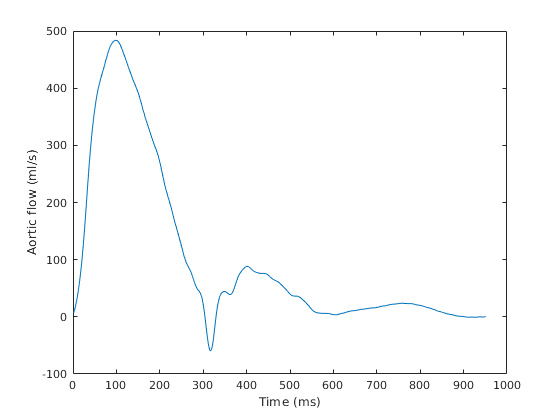


figure
plot(inp1(14000:14950,2))
xlabel("Time (ms)")
ylabel("Aortic flow (ml/s)")


% hold on
% plot()

## Sensitivity analysis and fitting the model

In this section, we will load data that correspond to the flow and pressure of a hypotensive subject with low blood pressure. Then we will perform the following steps:

- Sensitivity analysis to determine the initial values of the parameters for the estimation 

- Selection of parameters that need to be optimized.

- Fitting the parameters of the model.

- Determining the accuracy of the fitting since we already know the parameters for the hypotensive subject. 

Sensitivity analysis

% Modeling Case 1 - hypotensive subject
% Sensitivity analysis
out(:,2)=TFP(:,3); % we can also ake the BP signal from the hypotensive subject above
out(:,1)=TFP(:,1);

[EvalResult, ParamValues, p] = sensitivityEvaluationWK(out)

ps =   ParameterSpace with properties:

            ParameterNames: {'Z0'  'CA'  'R'  'L'}
    ParameterDistributions: [1×4 prob.UniformDistribution]
           RankCorrelation: []
                   Options: [1×1 sdo.SampleOptions]
                     Notes: []


EvalResult = 100×1 table
    CustomReq
    _________

      11921  
     3089.1  
     3234.9  
      10371  
     8186.9  
     2531.5  
     723.28  
     258.12  
      11628  
     3226.6  
     1057.6  
     941.97  
      15553  
     5639.9  
     1197.6  
     847.37  


ParamValues = 100×4 table
       Z0         CA          R           L     
    ________    _______    _______    __________

    0.092547     2.2169      1.819     0.0083316
    0.035726    0.95878     1.2587     0.0098353
    0.078148     1.4212     1.2736     0.0074374
    0.077836      2.064     1.7329     0.0037668
     0.04424     2.4506     1.6304     0.0060487
    0.061104    0.70281     1.1958     0.0015238
    0.016827     2.8235    0.44755     0.0091099
    0.014856     2.4393    0.55587     0.0088567
    0.057772      1.717     1.7844     0.0082687
    0.080125     1.5896    0.15448     0.0029769
    0.094061      1.617     1.0308     0.0061464
    0.021692     1.2659    0.41906    0.00071387
    0.061194     1.7713     1.9595       0.00454
    0.052245     1.7769     1.4541     0.0034708
    0.011071     2.5441     1.0509     0.0020341
    

 
p(1,1) =
 
       Name: 'Z0'
      Value: 0.0500
    Minimum: 0.0100
    Maximum: 0.1000
       Free: 1
      Scale: 0.0625
       Info: [1×1 struct]

 
p(2,1) =
 
       Name: 'CA'
      Value: 2
    Minimum: 0.5000
    Maximum: 3
       Free: 1
      Scale: 1
       Info: [1×1 struct]

 
p(3,1) =
 
       Name: 'R'
      Value: 0.6000
    Minimum: 0.1000
    Maximum: 2
       Free: 1
      Scale: 2
       Info: [1×1 struct]

 
p(4,1) =
 
       Name: 'L'
      Value: 0.0050
    Minimum: 5.0000e-04
    Maximum: 0.0100
       Free: 1
      Scale: 0.0312
       Info: [1×1 struct]

 
4x1 param.Continuous
 
lists of methods, superclasses
 


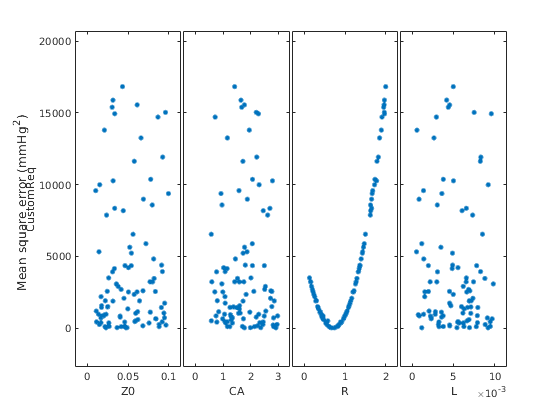


sdo.scatterPlot(ParamValues,EvalResult)
ylabel('Mean square error (mmHg^2)')

opts = sdo.AnalyzeOptions;
opts.Method = 'Correlation';
sensitivities = sdo.analyze(ParamValues,EvalResult, opts);
disp(sensitivities)

          CustomReq 
          __________

    Z0       0.07411
    CA    -0.0098785
    R        0.79831
    L      -0.066083



Selection of parameters

[fval, idx_min] = min(EvalResult.CustomReq);
L.Value = ParamValues.L(idx_min);
Z0.Value = ParamValues.Z0(idx_min);
R.Value = ParamValues.R(idx_min);
CA.Value = ParamValues.CA(idx_min);
L.Minimum=L.Value/2;
L.Maximum=L.Value*1.5;

Z0.Minimum=Z0.Value/2;
Z0.Maximum=Z0.Value*1.5;

R.Minimum=R.Value/2;
R.Maximum=R.Value*1.5;

CA.Minimum=CA.Value/2;
CA.Maximum=CA.Value*1.5;



Optimization

% Selection of parameters from the sensitivity analysis to be used in the
% optimization
Exp = sdo.Experiment(model_name);
v = [L Z0 R CA];
Exp = setEstimatedValues(Exp, v);   % use vector of parameters/states
Simulator = createSimulator(Exp);
% Simulator = sim(Simulator);
% % Retrieve logged signal data.
% SimLog = find(Simulator.LoggedData,get_param('WK','SignalLoggingName'));
% Sig_Log = find(SimLog,'Sig');


opts = sdo.OptimizeOptions;
opts.Method = 'fmincon';
estFcn = @(v) WK_OptEvalFcn(v, Simulator, Exp,out);
vOpt = sdo.optimize(estFcn, v, opts);


 Optimization started 03-Oct-2022 18:18:36

                               max                     First-order 
 Iter F-count        f(x)   constraint    Step-size    optimality
    0      9      29.4742            0
    1     22      24.7916            0        0.224     1.06e+03
    2     28      18.7014            0        0.664          179
    3     43      13.8511            0        0.207          649
    4     53      12.6566            0         0.36          587
    5     63       9.3618            0        0.559          354
    6     76      7.86881            0        0.154          485
    7     85      1.83424            0        0.388         23.8
    8     94       1.0593            0        0.373          115
    9    102     0.678989            0       0.0514         5.23
   10    110     0.654304            0       0.0173         4.68
   11    118     0.653235            0      0.00236        0.114
   12    119     0.653235            0     0.000235        0.114
Lo

disp(vOpt)

 
(1,1) =
 
       Name: 'L'
      Value: 0.0138
    Minimum: 0.0046
    Maximum: 0.0138
       Free: 1
      Scale: 0.0156
       Info: [1×1 struct]

 
(1,2) =
 
       Name: 'Z0'
      Value: 0.0385
    Minimum: 0.0238
    Maximum: 0.0713
       Free: 1
      Scale: 0.0625
       Info: [1×1 struct]

 
(1,3) =
 
       Name: 'R'
      Value: 0.7126
    Minimum: 0.3364
    Maximum: 1.0091
       Free: 1
      Scale: 1
       Info: [1×1 struct]

 
(1,4) =
 
       Name: 'CA'
      Value: 2.0364
    Minimum: 1.4539
    Maximum: 4.3616
       Free: 1
      Scale: 2
       Info: [1×1 struct]

 
1x4 param.Continuous
 
lists of methods, superclasses
 


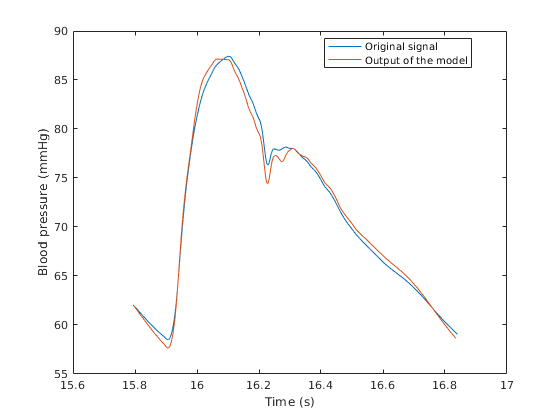



%% Visualizing Result of Optimization
%
% Obtain the model response after estimation.  Search for the
% model_residual signal in the logged simulation data.
Exp = setEstimatedValues(Exp, vOpt);   % use vector of parameters/states
Simulator = createSimulator(Exp);
Simulator = sim(Simulator);

figure
plot(out(start_pulse_ind:end_pulse_ind,1), out(start_pulse_ind:end_pulse_ind,2))
hold on
plot(Simulator.LoggedData.simout.Time(start_pulse_ind:end_pulse_ind), Simulator.LoggedData.simout.Data(start_pulse_ind:end_pulse_ind))
xlabel('Time (s)');
ylabel('Blood pressure (mmHg)');
legend({'Original signal', 'Output of the model'},'Location','Best')

function Vals = WK_OptEvalFcn(v,Simulator,Exp,out)
%WK_EVALFCN
%
% Function called at each iteration of the evaluation problem.
%
% The function is called with a set of parameter values, P, and returns
% the evaluated cost, Vals.
%
% See the sdoExampleCostFunction function and sdo.evaluate for a more
% detailed description of the function signature.
%

%% Model Evaluation
%start_pulse_ind=15800;
%end_pulse_ind=16841;
global start_pulse_ind;
global end_pulse_ind;
% Simulate the model.
Exp = setEstimatedValues(Exp, v);   % use vector of parameters/states
Simulator = createSimulator(Exp,Simulator);
Simulator = sim(Simulator);

% Retrieve logged signal data.
% SimLog = find(Simulator.LoggedData,get_param('WK','SignalLoggingName'));
% Sig_Log = find(SimLog,'PaSig');
PaSig=Simulator.LoggedData.simout.Data;
% Evaluate the design requirements.
Vals.F = mean((PaSig(start_pulse_ind:end_pulse_ind)-out(start_pulse_ind:end_pulse_ind,2)).^2);
end
